# Plot Function using fplot and piecewise

Julian Avila - 20212107030

Laura Herrera - 20212107011

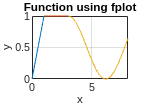

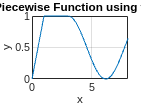

function plot_fuction(a, b, c)
    syms x

    y1 = a * x;
    y2 = a;
    y3 = (cos(x - b) + a) / 2;

    figure;
    fplot(y1, [0, a]);
    hold on;
    fplot(y2, [a, b]);
    fplot(y3, [b, c]);
    grid on;
    xlabel('x');
    ylabel('y');
    title('Function using fplot');

    f = piecewise(x <= a, y1, (a < x)jkjk < b , y2, b <= x, y3);

    figure;
    fplot(f, [0, c]);
    grid on;
    xlabel('x');
    ylabel('y');
    title('Piecewise Function using fplot');
end

plot_fuction(1, 3, 8);